## **ECE 569 Lab 3 Tutorial**

If you are new to MATLAB, this tutorial will help you with the basic commands you will need in order to complete this assignment.

clear all; % delete variables in current Workspace
close all; % close all figures (if any are open)
clc;       % clear the Command Window

#### **Vectors and Matrices**

MATLAB supports both row vectors and column vectors. Here are some examples:

row_vector_1 = zeros(1,6)   % 1 row, 6 columns

row_vector_1 =      0     0     0     0     0     0


row_vector_2 = 1:10         % 1,2,3,4,...,9,10

row_vector_2 =      1     2     3     4     5     6     7     8     9    10



column_vector_1 = ones(5,1) % 5 rows, 1 column

column_vector_1 =      1
     1
     1
     1
     1


column_vector_2 = (3:2:13)' % the ' is the transpose operator

column_vector_2 =      3
     5
     7
     9
    11
    13


Note that you can suppress output by using the semicolon ; at the end of the line.

x_data = rand(3,1); % remove the ; to see the output

To access an element inside a vector, use `()` for indexing. Note that in MATLAB, indexing starts at 1.

row_vector_1(2) = 17            % index 2

row_vector_1 =      0    17     0     0     0     0


row_vector_1(end) = 100         % end gives final index

row_vector_1 =      0    17     0     0     0   100


column_vector_1(end-1) = 2*3    % end-1 works too!

column_vector_1 =      1
     1
     1
     6
     1


You can also define vectors using brackets [ ]

small_primes = [2 3 5 7 11 13]  % row vector

small_primes =      2     3     5     7    11    13


gas_prices = [3.81; 3.99; 4.25] % column vector

gas_prices =     3.8100
    3.9900
    4.2500


Matrices are similarly defined and accessed.

R = ones(3,3)

R =      1     1     1
     1     1     1
     1     1     1


I = eye(3)

I =      1     0     0
     0     1     0
     0     0     1


M = [1 2 3; 4 5 6; 7 8 9]

M =      1     2     3
     4     5     6
     7     8     9



% Change the (2,3) element of R
R(2,3) = 200

R =      1     1     1
     1     1   200
     1     1     1



% Get the 3rd column of R.
% Think: Every row, 3rd column
R(:,3)

ans =      1
   200
     1



% Get the first row of M
% Think: first row, every column
M(1,:)

ans =      1     2     3



% Modify a section of a matrix
M(2:3,1:2) = -1*[11 12; 13 14]

M =      1     2     3
   -11   -12     6
   -13   -14     9



% Transpose a matrix
M'

ans =      1   -11   -13
     2   -12   -14
     3     6     9


You can construct a matrix from column vectors (and also row vectors).

c1 = [10; 20; 30];
c2 = [40; 50; 60];
C = [c1 c2]

C =     10    40
    20    50
    30    60


To check the size of a matrix of vector, use `size()`

size(C)

ans =      3     2


size(C,1) % number of rows

ans = 3

size(C,2) % number of columns

ans = 2

What about a list of matrices? Sometimes, we want to use a single variable to represent a bunch of different matrices of the same size. In this example, we have 5 matrices, $A_1 \dots A_5$ each of which is a 2x2 matrix.

A = zeros(2,2,5);
A(:,:,1) = ones(2,2);
A(:,:,2) = rand(2,2);
A(:,:,3) = [1 2; 3 4];
A(:,:,4) = A(:,:,1) + A(:,:,3);
A

A = A(:,:,1) =

     1     1
     1     1


A(:,:,2) =

    0.0318    0.0462
    0.2769    0.0971


A(:,:,3) =

     1     2
     3     4


A(:,:,4) =

     2     3
     4     5


A(:,:,5) =

     0     0
     0     0


Matrix multiplication, scalar multiplication, addition, subtraction work as you would expect, but MATLAB also allows for element-wise operators.

x = 1:4;
5*x

ans =      5    10    15    20


2+x

ans =      3     4     5     6


x.^2 % square each element

ans =      1     4     9    16


exp(x) % e^x1 e^x2 ...

ans =     2.7183    7.3891   20.0855   54.5982


sin(x) % sin(x1) sin(x2) ...

ans =     0.8415    0.9093    0.1411   -0.7568



A = magic(3);
B = diag([1 2 3])

B =      1     0     0
     0     2     0
     0     0     3


A*B    % matrix multiplication

ans =      8     2    18
     3    10    21
     4    18     6


A.*B   % element-wise multiplcation

ans =      8     0     0
     0    10     0
     0     0     6


Be careful with functions with matrices. Sometimes they are applied elementwise and sometimes they are applied to the entire matrix. If you don't know, use the `help` command in the Command Window

exp(A)   % element-wise exponential

ans = 1.0e+03 *

    2.9810    0.0027    0.4034
    0.0201    0.1484    1.0966
    0.0546    8.1031    0.0074


expm(A)  % matrix exponential

ans = 1.0e+06 *

    1.0898    1.0896    1.0897
    1.0896    1.0897    1.0897
    1.0896    1.0897    1.0897


help expm

 expm - Matrix exponential
    This MATLAB function computes the matrix exponential of X.

    Syntax
      Y = expm(X)

    Input Arguments
      X - Input matrix
        square matrix

    Examples
      Compare Exponentials

    See also exp, expm1, expmv, funm, logm, eig, sqrtm

    Introduced in MATLAB before R2006a
    Documentation for expm



**Plotting and Subplots**

We can plot two vectors (x vector, y vector) using the plot command. In this example, we simulate a spring-mass system with damping using a state space model (simulating a model is not required on this homework!)

t = [0:0.01:0.79]';  % time (s)
x = [0.599214325, 0.591303815, 0.583367236, 0.575195555, 0.566535987, ...
     0.557387584, 0.548012286, 0.538581297, 0.52890651, 0.51865972, ...
     0.507859448, 0.497000633, 0.486579456, 0.476500338, 0.466046002, ...
     0.454490908, 0.441741001, 0.428375764, 0.41511106, 0.402247553, ...
     0.389577539, 0.37670608, 0.363396998, 0.349659113, 0.335608681, ...
     0.321318682, 0.306793898, 0.292044766, 0.277143189, 0.262180975, ...
     0.24716432, 0.231962858, 0.216396123, 0.200397196, 0.184091645, ...
     0.167704631, 0.151391907, 0.135160762, 0.118916296, 0.102518474, ...
     0.085777431, 0.068474873, 0.05050687, 0.032038912, 0.013441609, ...
    -0.005016699, -0.023415747, -0.042068649, -0.061156697, -0.080543397, ...
    -0.099986553, -0.119461975, -0.139170943, -0.159233131, -0.179502813, ...
    -0.199783901, -0.220154383, -0.240919022, -0.262196873, -0.283685685, ...
    -0.304972601, -0.326048461, -0.347364857, -0.369316438, -0.391767101, ...
    -0.414204177, -0.436321537, -0.458309049, -0.48053487, -0.503091317, ...
    -0.525793073, -0.548542381, -0.571463452, -0.594581435, -0.617560345, ...
    -0.640040826, -0.66229238, -0.685294903, -0.709899516, -0.735854556]';

Now we have two vectors q and v which we would like to plot as functions of time. We need to use `subplot` to select which part of the figure to graph. We first tell subplot that we want the figures arranged in a (2,1) column vector, and then specify the index. If you wanted to plot 4 signals, then you would have the command `subplot(4,1,1) `and then `subplot(4,1,2), `etc. Sometimes you want to plot a row vector. That is not a problem either for the plot function.

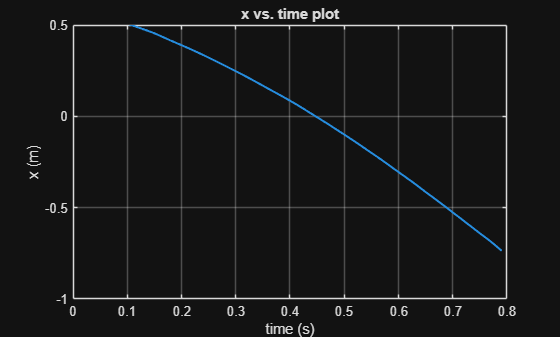

figure;
plot(t, x, 'LineWidth', 1.5);
grid on;

% Set axis labels and title
xlabel('time (s)');
ylabel('x (m)');
title('x vs. time plot');

% Customize axes
xlim([0 0.8]);                    % x-axis range
ylim([-1 0.5]);                   % y-axis range
xticks(0:0.1:0.8);                % x-axis ticks at 0.1 intervals
yticks(-1:0.5:0.5);               % y-axis ticks from -1 to 0.5 in steps of 0.5

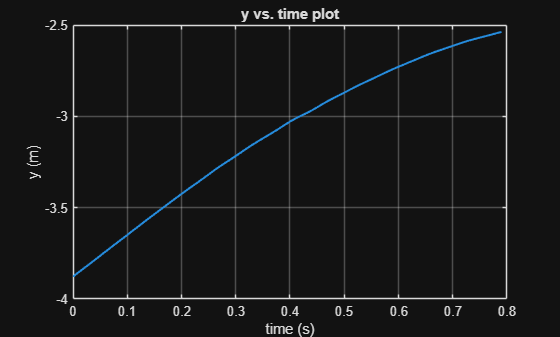

t = [0:0.01:0.79]';
y = [-3.877638444, -3.854317608, -3.831587044, -3.809269631, -3.786663, ...
     -3.763458714, -3.740123885, -3.717271725, -3.694884253, -3.672393386, ...
     -3.649444598, -3.626298605, -3.603401642, -3.580800778, -3.558209436, ...
     -3.535541672, -3.513079891, -3.491029073, -3.469150877, -3.447079767, ...
     -3.424911502, -3.403181086, -3.382149885, -3.361331871, -3.339978059, ...
     -3.318006474, -3.296224877, -3.275519456, -3.255936728, -3.236689803, ...
     -3.217001512, -3.196799058, -3.176621295, -3.15706372, -3.138407422, ...
     -3.120570606, -3.103120968, -3.085346543, -3.066681079, -3.047381505, ...
     -3.028696339, -3.011970752, -2.99731532, -2.983245794, -2.967891846, ...
     -2.950678399, -2.932761794, -2.915788595, -2.900326842, -2.885577088, ...
     -2.87047715, -2.854848282, -2.839395824, -2.824783716, -2.810932092, ...
     -2.797218414, -2.783178389, -2.76889912, -2.754826301, -2.741343835, ...
     -2.728537576, -2.716209371, -2.704013288, -2.691655421, -2.679124153, ...
     -2.666784986, -2.655158704, -2.644486052, -2.634479211, -2.624550852, ...
     -2.614338744, -2.604024174, -2.594146359, -2.585118527, -2.576910704, ...
     -2.569142919, -2.561419547, -2.55356513, -2.545604764, -2.537610387]';


figure;
plot(t, y, 'LineWidth', 1.5);
grid on;

% Labels and title
xlabel('time (s)');
ylabel('y (m)');
title('y vs. time plot');

% Axis customization
xlim([0 0.8]);                    % X-axis range
ylim([-4 -2.5]);                  % Y-axis range
xticks(0:0.1:0.8);                % X-axis ticks every 0.1
yticks(-4:0.5:-2.5);

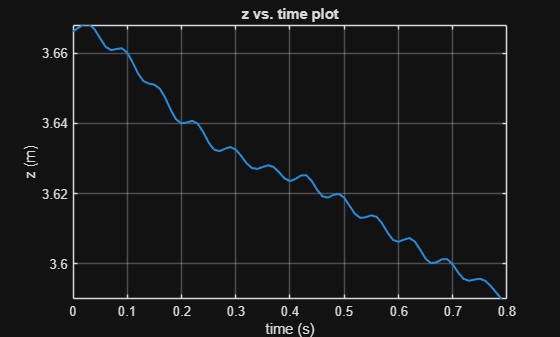

t = [0:0.01:0.79]';
z = [3.666114093, 3.66722183, 3.668093761, 3.668119649, 3.666727717, ...
     3.664213725, 3.661848566, 3.660842492, 3.661140154, 3.661377528, ...
     3.660147423, 3.657323739, 3.654141772, 3.65201866, 3.651295055, ...
     3.651023427, 3.64987102, 3.64727321, 3.643901513, 3.641139008, ...
     3.639995176, 3.640282744, 3.640715269, 3.639912082, 3.637532589, ...
     3.634568745, 3.632507886, 3.632092865, 3.632768885, 3.633239554, ...
     3.632545653, 3.630725704, 3.628639737, 3.627266571, 3.627043952, ...
     3.627614347, 3.62806612, 3.627566358, 3.626037631, 3.624330688, ...
     3.623579682, 3.624155052, 3.625183399, 3.625228726, 3.623607708, ...
     3.621081951, 3.619200084, 3.618884971, 3.619612146, 3.61993298, ...
     3.618800333, 3.616460151, 3.614168867, 3.613080522, 3.613293928, ...
     3.613809363, 3.613367181, 3.611479342, 3.608847043, 3.606819881, ...
     3.606290484, 3.606913834, 3.607348515, 3.606385138, 3.604014995, ...
     3.60147213, 3.600166856, 3.600447724, 3.601310345, 3.601308805, ...
     3.599822554, 3.597533166, 3.595735209, 3.595181903, 3.595525588, ...
     3.595766626, 3.595161362, 3.593704775, 3.591854707, 3.589960738]';

figure;
plot(t, z, 'LineWidth', 1.5);
grid on;

xlabel('time (s)');
ylabel('z (m)');
title('z vs. time plot');

% Axis limits and ticks
xlim([0 0.8]);
ylim([3.59 3.668]);
xticks(0:0.1:0.8);
yticks(3.5:0.02:3.7);   % <-- y-axis in steps of 0.02 m

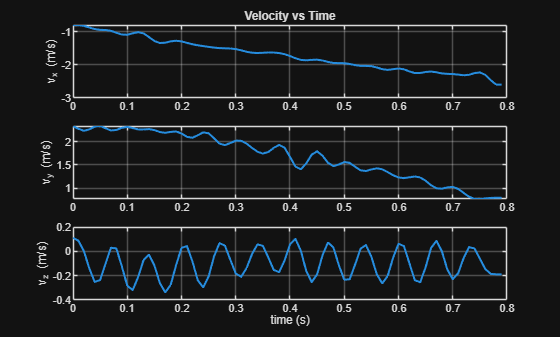

% Load or define your position and time vectors
% (Assume t, x, y, z already defined as column vectors)

N = length(t);
v = zeros(N,3);       % velocity matrix: [vx, vy, vz]

for i = 1:N-1
    dt = t(i+1) - t(i);                 % time difference
    v(i,1) = (x(i+1) - x(i)) / dt;     % vx
    v(i,2) = (y(i+1) - y(i)) / dt;     % vy
    v(i,3) = (z(i+1) - z(i)) / dt;     % vz
end

% For the last entry, define v(N,:) same as previous to keep same length
v(N,:) = v(N-1,:);

figure;

subplot(3,1,1);
plot(t, v(:,1), 'LineWidth', 1.5);
grid on;
ylabel('v_x (m/s)');
title('Velocity vs Time');

subplot(3,1,2);
plot(t, v(:,2), 'LineWidth', 1.5);
grid on;
ylabel('v_y (m/s)');

subplot(3,1,3);
plot(t, v(:,3), 'LineWidth', 1.5);
grid on;
xlabel('time (s)');
ylabel('v_z (m/s)');
ylim([-0.4 0.2]);


dt = mean(diff(t));
v = [diff(x)/dt, diff(y)/dt, diff(z)/dt];
v(end+1,:) = v(end,:);   % pad last row

**Loops**

Best seen with an example or two.

N = 10;
A = zeros(3,3,N);

for i=1:N
    A(:,:,i) = i * ones(3,3);
end
A

A = A(:,:,1) =

     1     1     1
     1     1     1
     1     1     1


A(:,:,2) =

     2     2     2
     2     2     2
     2     2     2


A(:,:,3) =

     3     3     3
     3     3     3
     3     3     3


A(:,:,4) =

     4     4     4
     4     4     4
     4     4     4


A(:,:,5) =

     5     5     5
     5     5     5
     5     5     5


A(:,:,6) =

     6     6     6
     6     6     6
     6     6     6


A(:,:,7) =

     7     7     7
     7     7     7
     7     7     7


A(:,:,8) =

     8     8     8
     8     8     8
     8     8     8


A(:,:,9) =

     9     9     9
     9     9     9
     9     9     9


A(:,:,10) =

    10    10    10
    10    10    10
    10    10    10



% compute row sums of A_i
A_first_row_sums = zeros(N,1);
for i=1:N
    Ai = A(:,:,i);  % get the ith matrix
    A_first_row_sums(i) = sum(Ai(1,:));
end
A_first_row_sums'

ans =      3     6     9    12    15    18    21    24    27    30


**If ElseIf Else**

N = 10;
A = zeros(3,3,N);

for i=1:N
    if mod(i,3) == 0
        % i = 3,6,9,...
        A(:,:,i) = 3*ones(3,3);
    elseif mod(i,3) == 1
        % i = 1,4,7,...
        A(:,:,i) = ones(3,3);
    else
        A(:,:,i) = 2*ones(3,3);
    end
end
A

A = A(:,:,1) =

     1     1     1
     1     1     1
     1     1     1


A(:,:,2) =

     2     2     2
     2     2     2
     2     2     2


A(:,:,3) =

     3     3     3
     3     3     3
     3     3     3


A(:,:,4) =

     1     1     1
     1     1     1
     1     1     1


A(:,:,5) =

     2     2     2
     2     2     2
     2     2     2


A(:,:,6) =

     3     3     3
     3     3     3
     3     3     3


A(:,:,7) =

     1     1     1
     1     1     1
     1     1     1


A(:,:,8) =

     2     2     2
     2     2     2
     2     2     2


A(:,:,9) =

     3     3     3
     3     3     3
     3     3     3


A(:,:,10) =

     1     1     1
     1     1     1
     1     1     1


**Inline Functions**

You can create your own one-line functions. The syntax is a little strange, but not difficult with practice.

my_sum = @(x,y) x+y;
z = my_sum(3,4)

z = 7


my_matrix = @(x) [0 x 0; 0 0 x; x 0 0];
A = my_matrix(7)

A =      0     7     0
     0     0     7
     7     0     0


**Functions**

For functions that take multiple lines, you can either put them into their own .m file (with the same name as the function itself) or put them at the bottom of your live script.

[s,d] = Add_Sub(5,7)

s = 12

d = -2

s1 = My_Square(12)

s1 = 144

s2 = My_Square(-3) % ALWAYS test your functions!

s2 = 0

function [the_sum, the_diff] = Add_Sub(x,y)
    the_sum = x+y;
    the_diff = x-y;
end

function y = My_Square(n)
total = 0;
for i=1:n
    total = total + n;
end
y = total;
end